cal_data=[8 485;
12	387;
16	295;
20	237;
24	198;
19	249;
11	408]

cal_data =     8.00000000000000e+000    485.000000000000e+000
    12.0000000000000e+000    387.000000000000e+000
    16.0000000000000e+000    295.000000000000e+000
    20.0000000000000e+000    237.000000000000e+000
    24.0000000000000e+000    198.000000000000e+000
    19.0000000000000e+000    249.000000000000e+000
    11.0000000000000e+000    408.000000000000e+000


f=fit(cal_data(:,2),cal_data(:,1),'poly2')

f =      Linear model Poly2:
     f(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =   0.0001066  (2.694e-05, 0.0001862)
       p2 =     -0.1252  (-0.1796, -0.07094)
       p3 =       44.02  (35.41, 52.63)

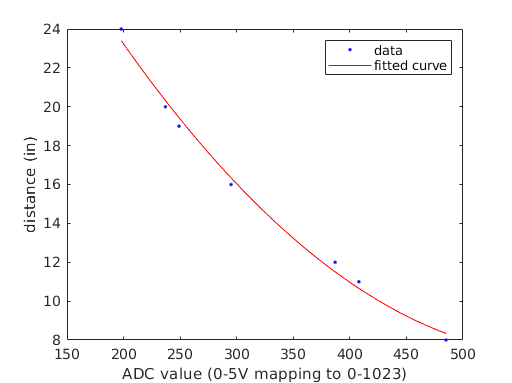

plot(f,cal_data(:,2),cal_data(:,1))
xlabel("ADC value (0-5V mapping to 0-1023)")
ylabel("distance (in)")

load("12inHDW")

flatPoints = abs(data(1:end,2)) < .3;%
flat_start = 20;
test = (~mod(1:(length(data(:,1))-flat_start),36)')

test = 1278×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


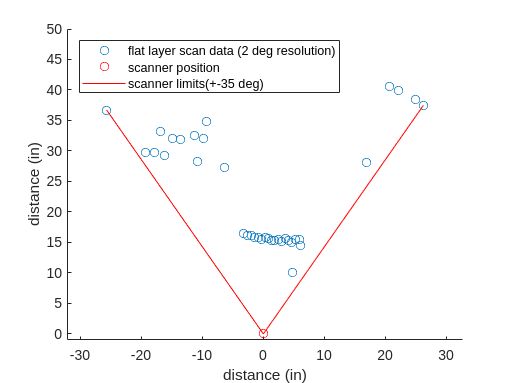

scanflats = [false(flat_start-1,1); true; (~mod(1:(length(data(:,1))-flat_start),36)')];
flatData = data(scanflats,:);
scatter(flatData(:,1),flatData(:,3))

hold on
scatter(0,0,'r')
plot([flatData(1,1) 0],[flatData(1,3) 0],'r')
plot([flatData(end,1) 0],[flatData(end,3) 0],'r')
legend("flat layer scan data (2 deg resolution)","scanner position","scanner limits(+-35 deg)","Location",'northwest')
xlabel("distance (in)")
ylabel("distance (in)")
ylim([-1,50])
axis equal
hold off